# Search for fluorophores based on 500-600nm data

We ask whether we can find three fluorophores defined as Skewed Gaussians, one of which has blood applied to it, that can fit the lip and tongue data. 

We find the parameters for the skewed Gaussian using for the range 500-600 nm

- create fluorophore structure for FAD and NADH from data/sources/Wu&Qu

- fit positively-skewed gaussian distribution to  collagen, keratin, FAD and NADH (all from Wu&Qu data)

- Use mean and std of FAD,NADH and blood-attenuated collagen as starting functions to fit lip data 

- use a) the best-fitting basis functions from Step 3, and b) the mean and std dev of keratin as starting function, to fit tongue data 

Another thing to try is for range 500-700 nm

- use mean and std of FAD,NADH and blood-attenuated collagen from Step 3 of 500-600 nm (above) as starting functions to fit lip data (over range of 500-700 nm)

- use mean and std of FAD,NADH and blood-attenuated collagen from Step 1 of 500-700 nm, AND mean and std of keratin from Step 4 of 500-600 nm, AND porphyrins and chlorophyll as spectral basis functions to fit tongue data

See also:  s_oeBloodFluorophoreTongueSrch.mlx, s_oeBloodFluorophoreLip.srch.mlx

## Initialize

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;
subjects = {'Z','B','D','J'};

oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
oxyblood.opticalDensity = 15;
oxyTransmittance = oxyblood.transmittance;

## Fit all the subjects at once for both tongue and lip

The goal is to have the same fluorophores for all the fitting, and that we allow the weights, but not the fluorophores to vary.

We fix the blood density above, too.  In some of the other scripts we searched for effective blood density.  These differed between tongue and lip but here it seems the impact is not that large.

Here are the data for tongue, lip and all subjects.

Tfiles405 = ieTableGet(T,'substrate','tongue','e wave',405);
Tfiles415 = ieTableGet(T,'substrate','tongue','e wave',415);
Tnum = size(Tfiles405,1) + size(Tfiles415,1);

Lfiles405 = ieTableGet(T,'substrate','lip','e wave',405);
Lfiles415 = ieTableGet(T,'substrate','lip','e wave',415);
Lnum = size(Lfiles405,1) + size(Lfiles415,1);

allFiles = cat(1,Tfiles405,Tfiles415,Lfiles405,Lfiles415);
allData = oeReadFiles(allFiles,'normalized wave',normWave,'wave',wave);
assert(size(allFiles,1) - (Lnum + Tnum) == 0);

% plot(wave,oxyTransmittance);

Find the parameters, weights and skewedG has the fluorophores and the blood.

[global_params, wgtsNN, skewedG] = ...
    oeSolveFluorophoresSkewedGaussians(wave, allData, oxyTransmittance);
disp('Optimized Gaussian Parameters:');

Optimized Gaussian Parameters:


name = {'collagen','keratin','FAD   '};
for ii=1:3
    fprintf('%s - Peak: %.1f Spread: %.1f Skew: %.1f\n',name{ii},global_params(ii:3:end));
end

collagen - Peak: 404.5 Spread: 137.9 Skew: -1.5
keratin - Peak: 498.1 Spread: 25.4 Skew: 0.2
FAD    - Peak: 534.5 Spread: 54.6 Skew: 0.0



% Plot these in 3-space to see if they cluster, which they must
disp('Non-Negative Tongue Weights');

Non-Negative Tongue Weights


tongueWeights = wgtsNN(:,1:Tnum);
disp(tongueWeights)

    2.3063    2.4460    2.1666    1.6985    1.7214    1.6605    1.7800    2.3805    2.0043    2.1766    1.8612    1.9725    2.0063    2.6381    2.3580    2.3943    2.2448    2.5682    2.2904    2.3662    2.1996    1.8844    1.7511    1.8327    1.6943    1.7596    1.7017    1.9070    1.7717    1.8029    1.7421    1.8356    1.8674    1.8136    1.7504    1.6424    1.7495    2.1691    2.1504    2.1694    2.1926    1.9862    1.8477    2.1508    2.0919    2.0990    1.9836    2.0405    1.9425    1.8786    1.7979    2.0102    1.8563    2.1594    2.2476    2.2849    1.5386    1.5968    1.5878    2.2063    2.0358    2.2161    1.9568    1.9586    1.9721    1.8896
    0.3130    0.3134    0.3881    0.4398    0.4167    0.3941    0.4597    0.4508    0.3895    0.4095    0.4844    0.4387    0.4916    0.4883    0.4857    0.5082    0.5171    0.4804    0.4805    0.5009    0.5131    0.2778    0.3290    0.2834    0.3699    0.3150    0.3267    0.2957    0.4645    0.3704    0.3745    0.3592    0.4079    0.324


disp('Non-negative Lip Weights')

Non-negative Lip Weights


lipWeights = wgtsNN(:,(Tnum+1):end);
disp(lipWeights)

    1.9123    1.7081    1.6952    2.3283    2.2179    2.3437    2.6992    2.3977    2.6237    1.8552    1.7996    1.8754    2.0554    2.3223    2.8560    2.9031    2.2922    2.3772    2.7226    2.7610    2.3717    2.3567    2.3387    2.3656    2.4392    2.4750    2.4682    2.4672    2.2076    2.2880    1.7644    1.9345    2.0706    1.9068    2.3783    2.1544    1.7246    1.7172    1.5896    1.6004    1.7574    1.6955    1.8420    1.8364    1.4876    1.4783    1.4447    1.4548    1.5185    1.4688    1.5136    1.5034    1.6330    1.6689    1.6975    2.3532    2.3831    2.3523    2.7691    2.6408    1.8911    2.0393    1.9754
    0.8022    0.8007    0.7472    0.7539    0.7036    0.7555    0.7517    0.7901    0.7904    0.8548    0.8775    0.8574    0.7585    0.7527    0.7218    0.7094    0.7387    0.7257    0.7424    0.7293    0.6625    0.6921    0.6341    0.6183    0.6651    0.6597    0.6864    0.6863    0.6810    0.6735    0.8023    0.7828    0.7767    0.7821    0.7245    0.7175    0.698

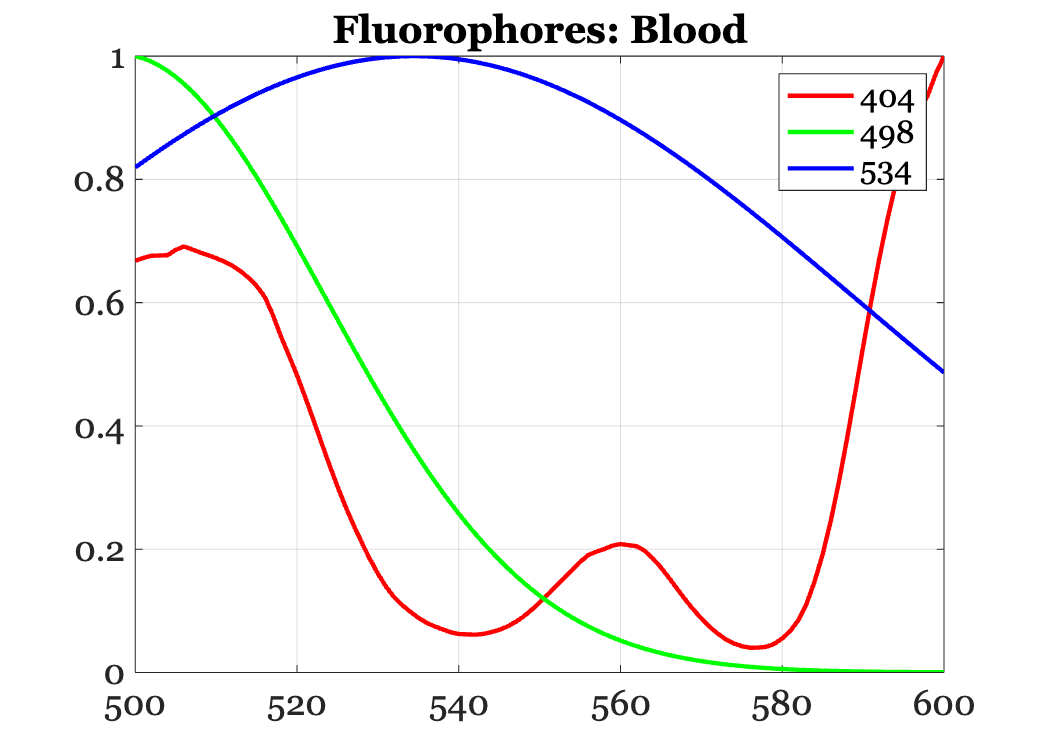


ieFigure;
mx = max(skewedG);
plot(wave,skewedG*diag(1./mx),'LineWidth',2);
title('Fluorophores: Blood');
lgn = legend({num2str(round(global_params(1))),num2str(round(global_params(2))),num2str(round(global_params(3)))});
grid on;

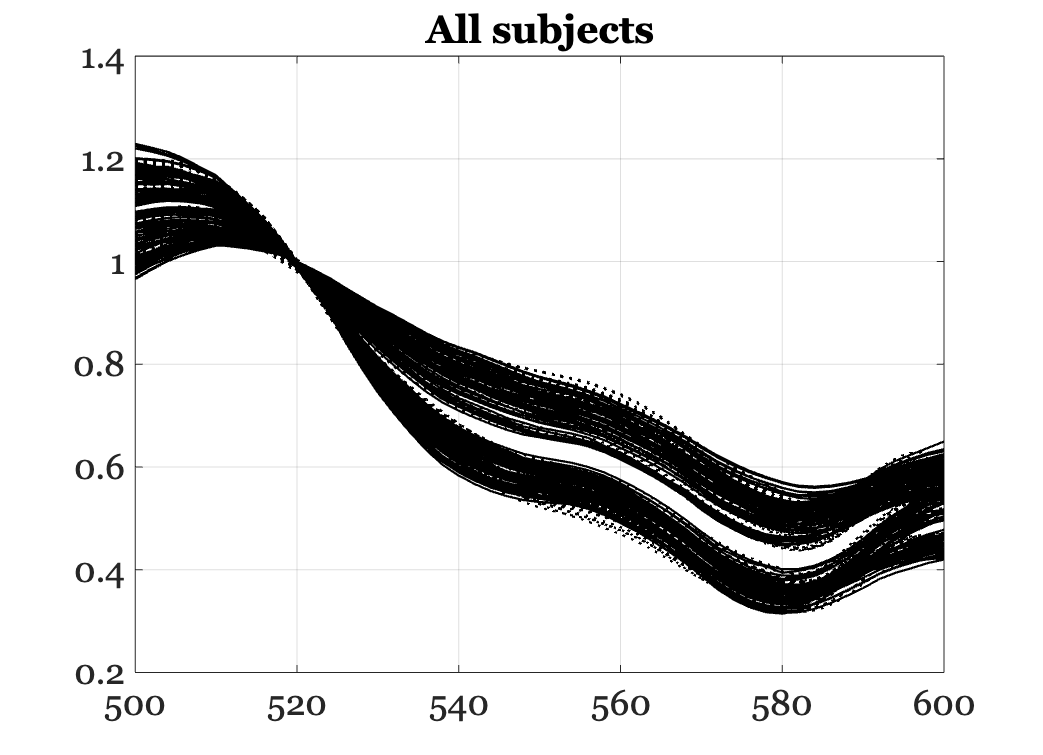


ieFigure;
plot(wave,allData,'k-',wave,skewedG*wgtsNN,'k:');
grid on; title('Fits')
title(sprintf('All subjects'));

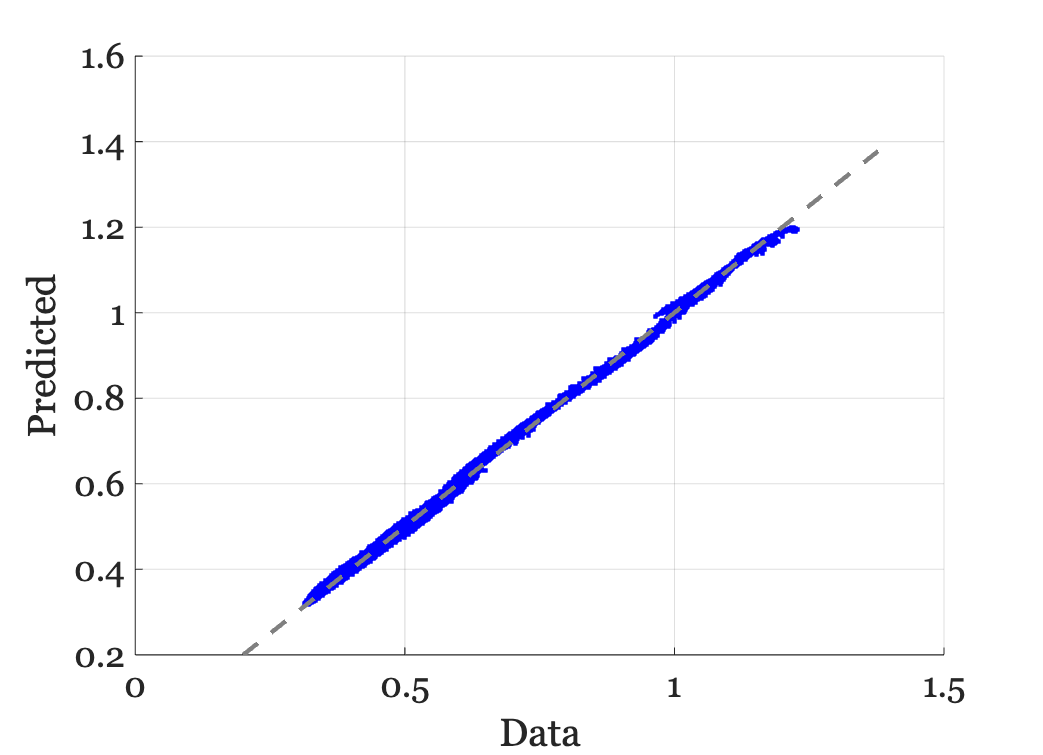


ieFigure;
tmp = skewedG*wgtsNN;
scatter(allData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');

## 3D plot of the weights

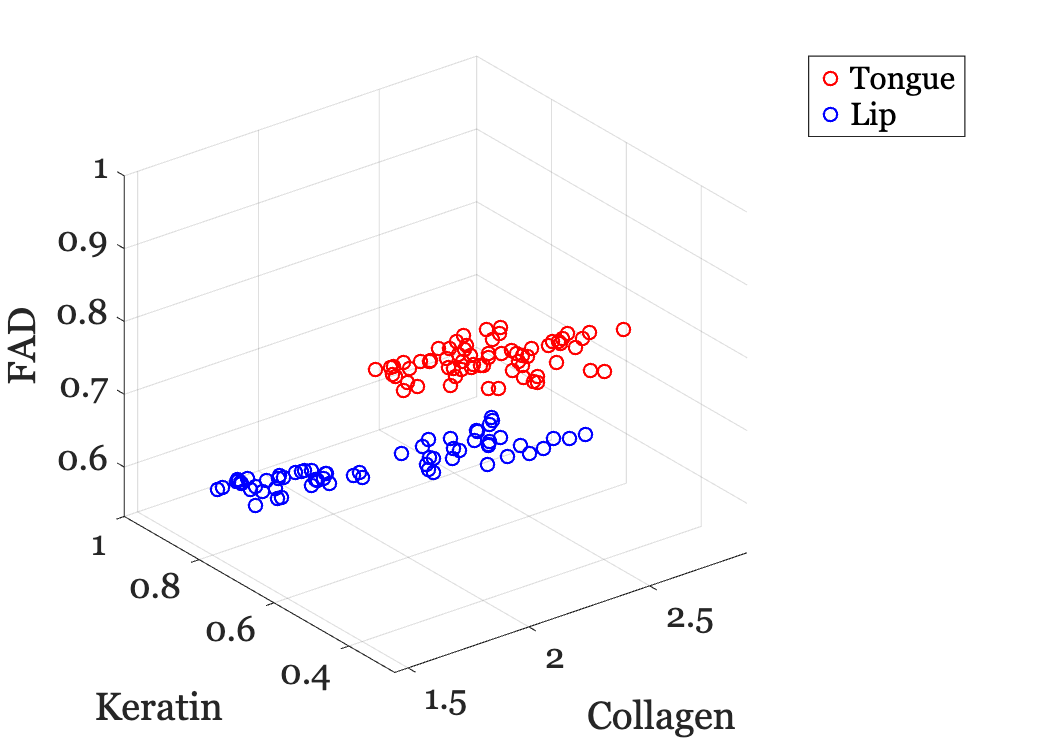

ieFigure;
plot3(tongueWeights(1,:),tongueWeights(2,:),tongueWeights(3,:),'ro');
hold on;
plot3(lipWeights(1,:),lipWeights(2,:),lipWeights(3,:),'bo');
grid on;
xlabel('Collagen'); ylabel('Keratin'); zlabel('FAD');
legend({'Tongue','Lip'});

## Try to fit the lip data using two or three fluorophores

Different blood conditions are implemented.

nFluorophores is (2, 3, or  3.1)

- If 2, the first has blood applied

- If 3, the first two have blood applied

- If 3.1, only the first of the three has blood applied.

Including a 3rd one attenuated by blood does not improve the result.  A 3rd one that is a regular skewed Gaussian does fit better.

nFluorophores = 3.1;

lipData = allData(:,(Tnum+1:end));
%{
oxyblood.opticalDensity = 15;
oxyTransmittance = oxyblood.transmittance;
%}

[global_params, lipWeights, skewedG2] = ...
    oeSolveFluorophoresSkewedGaussiansLip(wave, lipData, ...
    oxyTransmittance,nFluorophores);

disp('Optimized Gaussian Parameters:');

Optimized Gaussian Parameters:


for ii=1:round(nFluorophores)
    fprintf('%d - Peak: %.1f Spread: %.1f Skew: %.1f\n',...
        ii,global_params(ii:round(nFluorophores):end));
end

1 - Peak: 404.0 Spread: 124.8 Skew: -0.0
2 - Peak: 499.1 Spread: 23.0 Skew: -0.0
3 - Peak: 528.3 Spread: 52.4 Skew: -0.1


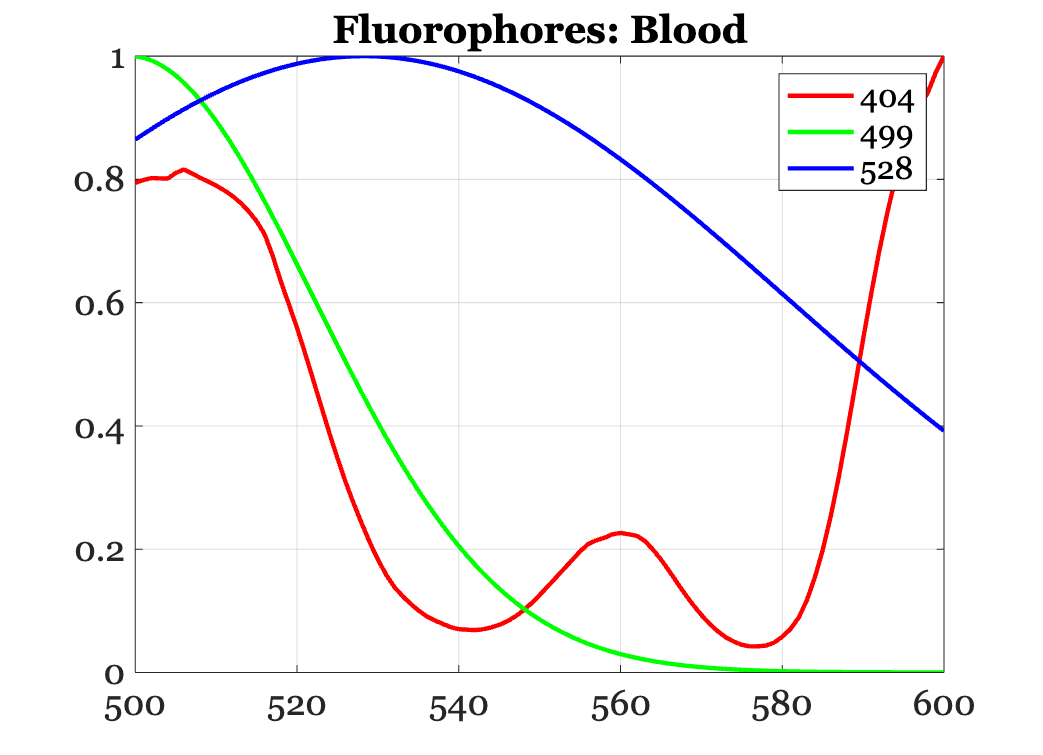


ieFigure;
mx = max(skewedG2);
plot(wave,skewedG2*diag(1./mx),'LineWidth',2);
title('Fluorophores: Blood');
if nFluorophores == 2
lgn = legend({num2str(round(global_params(1))),...
    num2str(round(global_params(2)))});
else
lgn = legend({num2str(round(global_params(1))),...
    num2str(round(global_params(2))), ...
    num2str(round(global_params(3)))});
end

grid on;

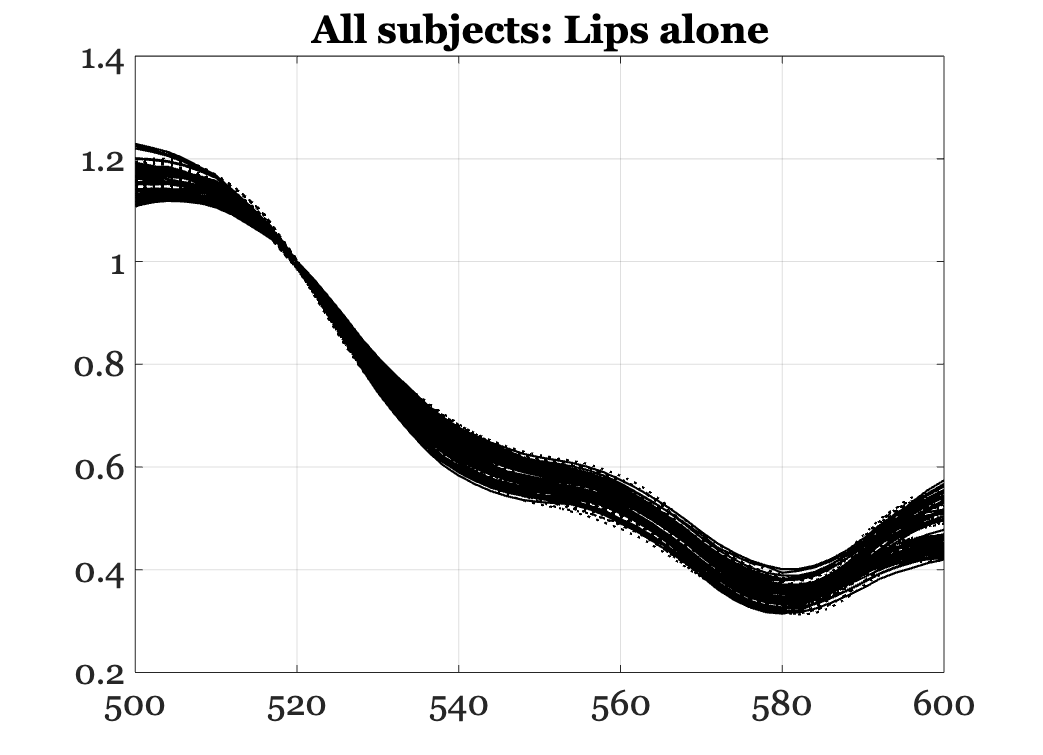


ieFigure;
plot(wave,lipData,'k-',wave,skewedG2*lipWeights,'k:');
grid on; title('Fits')
title(sprintf('All subjects: Lips alone'));

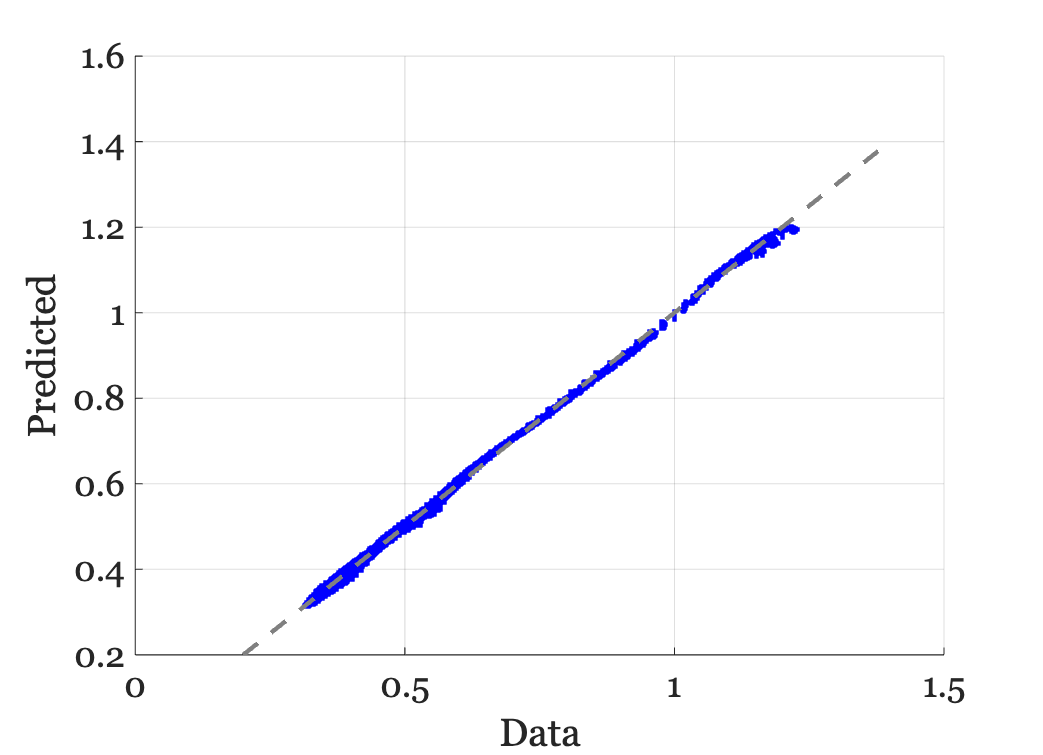


ieFigure;
tmp = skewedG2*lipWeights;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');